# Bài tập lớn Động lực học và Điều khiển (ME3011) - Lớp DT01 - Học kỳ 243

Sinh viên thực hiện: Nguyễn Đức Đạt, Trần Quang Đạo 

## 1. Khai báo các biến, các ma trận và các hàm truyền

Khai báo các hằng số:

x = 9;
y = 7;
z = 2;

m1 = (x + y + z) / 10;
m2 = (y + z) / 20;
L = (y + z) / 20;
B = (x + z) / (10 * y);
b = (x + y) / (10 * z);
g = 9.81;

Khai báo các ma trận:

A = [0  1           0                   0;
    0   (-B/m1)     (-m2*g/m1)          (-b/(m1*L));
    0   0           0                   1;
    0   (-B/(m1*L)) (-(m1+m2)*g/(m1*L)) (-(m1+m2)*b/(m1*m2*L^2))];
B_ = [0; (1/m1); 0; (1/(m1*L))];
C = [1 0 0 0; 0 0 1 0];
D = zeros(2,1);
sys = ss(A, B_, C, D)


sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0  -0.0873   -2.453  -0.9877
   x3        0        0        0        1
   x4        0   -0.194   -27.25   -10.97
 
  B = 
           u1
   x1       0
   x2  0.5556
   x3       0
   x4   1.235
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


Các hàm truyền:

G = tf(sys);
G1 = G(1) % Hàm truyền quan hệ giữa vị trí và lực


G1 =
 
      0.5556 s^2 + 4.877 s + 12.11
  -------------------------------------
  s^4 + 11.06 s^3 + 28.02 s^2 + 1.903 s
 
Continuous-time transfer function.


G2 = G(2) % Hàm truyền quan hệ giữa góc lắc và lực


G2 =
 
         1.235 s + 1.938e-16
  ---------------------------------
  s^3 + 11.06 s^2 + 28.02 s + 1.903
 
Continuous-time transfer function.


save('bien.mat', "sys", 'G1', 'G2', "m1", "m2", "L", "B", "b", "g");

## 2. Phân tích hệ thống

Tải các biến từ tệp **bien.mat**.

load('bien.mat');

Tệp Simulink để phân tích hệ thống

open_system('phan_tich_he_thong_ode')

## 3. Thiết kế và kiểm chứng hệ thống điều khiển

### 3.1. Con lắc đơn

#### 3.1.1. Thiết kế bộ điều khiển PID

Tải các biến từ tệp **bien.mat**.

load('bien.mat');

Thiết kế bộ điều khiển PID thỏa $T_s < 5$ giây và sai số góc quanh vị trí cân bằng là 0.05 rad. Tệp thiết kế được lưu với tên **thiet_ke_PID_con_lac.mat.**

controlSystemDesigner('rlocus', G2);
pause;

Lưu giá trị bộ điều khiển PID vào tệp **PID_con_lac.mat**.

C_PID_con_lac = tf(C_PID_con_lac);
Kpc = C_PID_con_lac.Numerator{1}(2)

Kpc =        50.665


Kdc = C_PID_con_lac.Numerator{1}(1)

Kdc =         6.525


Kic = C_PID_con_lac.Numerator{1}(3)

Kic =        98.716


save('PID_con_lac.mat', 'Kpc', 'Kic', 'Kdc');

#### 3.1.2. Kiểm chứng bộ điều khiển PID

Tải các biến từ tệp **bien.mat** và các hệ số PID từ tệp **PID_con_lac.mat**.

load('bien.mat')
load('PID_con_lac.mat');

Tệp Simulink để kiểm chứng bộ điều khiển PID của con lắc.

open_system('kiem_chung_con_lac');

### 3.2. Thiết kế bộ điều khiển PID cho xe đẩy

#### 3.2.1. Thiết kế bộ điều khiển PID

Tải các biến từ tệp **bien.mat**.

load('bien.mat');

Thiết kế bộ điều khiển PID thỏa $T_s < 3$ giây và độ vọt lố là 15%.

controlSystemDesigner('rlocus', G1);
pause;

Lưu giá trị bộ điều khiển PID vào tệp **PID_xe_day.mat**.

C_PID_xe_day = tf(C_PID_xe_day);
Kpx = C_PID_xe_day.Numerator{1}(2)

Kpx =        2786.3


Kdx = C_PID_xe_day.Numerator{1}(1)

Kdx =        159.39


Kix = C_PID_xe_day.Numerator{1}(3)

Kix =         25638


save('PID_xe_day.mat', 'Kpx', 'Kix', 'Kdx');

#### 3.2.2. Kiểm chứng bộ điều khiển PID

Tải các biến từ tệp **bien.mat** và các hệ số PID từ tệp **PID_xe_day.mat**.

load('bien.mat')
load('PID_xe_day.mat');

Tệp Simulink để kiểm chứng bộ điều khiển PID của xe đẩy.

open_system('kiem_chung_xe_day');

### 3.3. Thiết kế bộ điều khiển không gian trạng thái 

#### 3.3.1. Thiết kế bộ điều khiển không gian trạng thái

Tải các biến từ tệp **bien.mat**.

load('bien.mat');

Kiểm tra tính điều khiển được và quan sát được của hệ thống

rank(ctrb(sys.A, sys.B)), rank(obsv(sys.A, sys.C))

ans = 4

ans = 4

Tìm các cực thống trị của hệ theo yêu cầu thiết kế của vị trí xe đẩy x

Ts = 5;             % Thời gian xác lập 
Tr = 0.5;           % Thời gian tăng
wn = 1.8 / Tr;      % Tần số tự nhiên
z = 4 / (Ts * wn);  % Tỉ số giảm chấn
p_ = -wn*z + 1j*wn*sqrt(1-z^2);  % Cặp cực thống trị

Chọn các cực khác xa trục ảo $$j\omega$$ 5 lần so với cặp cực thống trị.

Đáp ứng của vị trí xe đẩy x với đầu vào [xd θd] = [1 0]:
Thời gian tăng: 0.284163 giây.
Thời gian xác lập: 6.442950 giây.
Độ vọt lố : 70.536219%.
Giá trị đỉnh: 1.705362.
Thời gian đỉnh: 0.845020 giây.

Đáp ứng của góc lắc con lắc θ với đầu vào [xd θd] = [1 0]:
Giá trị đỉnh: 0.720018.
Thời gian đỉnh: 1.153519 giây.


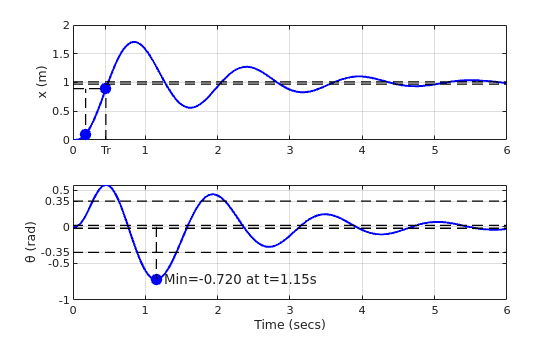

p = [p_ conj(p_) 5*real(p_) 5*real(p_) 5*real(p_) 5*real(p_)];
[K, Ke, sysC, thong_tin] = bo_dieu_khien_con_lac_xe_day(sys, p, 6);

Chọn các cực khác xa trục ảo $$j\omega$$ 10 lần so với cặp cực thống trị.

Đáp ứng của vị trí xe đẩy x với đầu vào [xd θd] = [1 0]:
Thời gian tăng: 0.163745 giây.
Thời gian xác lập: 2.701316 giây.
Độ vọt lố : 72.991323%.
Giá trị đỉnh: 1.729913.
Thời gian đỉnh: 0.528816 giây.

Đáp ứng của góc lắc con lắc θ với đầu vào [xd θd] = [1 0]:
Giá trị đỉnh: 0.971167.
Thời gian đỉnh: 0.283028 giây.


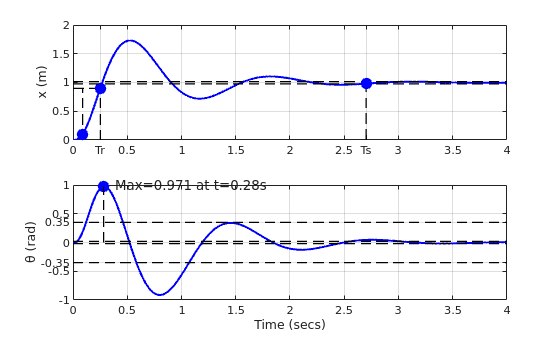

p = [p_ conj(p_) 10*real(p_) 10*real(p_) 10*real(p_) 10*real(p_)];
[K, Ke, sysC, thong_tin] = bo_dieu_khien_con_lac_xe_day(sys, p, 4);

Chọn các cực khác xa trục ảo $$j\omega$$ 3 lần so với cặp cực thống trị.

Đáp ứng của vị trí xe đẩy x với đầu vào [xd θd] = [1 0]:
Thời gian tăng: 0.433415 giây.
Thời gian xác lập: 6.500586 giây.
Độ vọt lố : 46.476737%.
Giá trị đỉnh: 1.464767.
Thời gian đỉnh: 1.165098 giây.

Đáp ứng của góc lắc con lắc θ với đầu vào [xd θd] = [1 0]:
Giá trị đỉnh: 0.423073.
Thời gian đỉnh: 1.435567 giây.


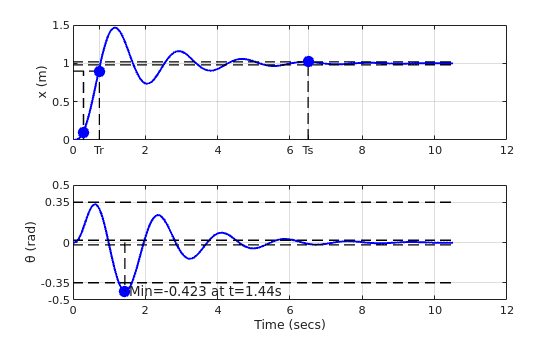

p = [p_ conj(p_) 3*real(p_) 3*real(p_) 3*real(p_) 3*real(p_)];
[K, Ke, sysC, thong_tin] = bo_dieu_khien_con_lac_xe_day(sys, p, 77);

Chọn các cực khác xa trục ảo $$j\omega$$ 1 lần so với cặp cực thống trị.

Đáp ứng của vị trí xe đẩy x với đầu vào [xd θd] = [1 0]:
Thời gian tăng: 1.992884 giây.
Thời gian xác lập: 5.483357 giây.
Độ vọt lố : 3.347084%.
Giá trị đỉnh: 1.033471.
Thời gian đỉnh: 4.259782 giây.

Đáp ứng của góc lắc con lắc θ với đầu vào [xd θd] = [1 0]:
Giá trị đỉnh: 0.061097.
Thời gian đỉnh: 0.978599 giây.


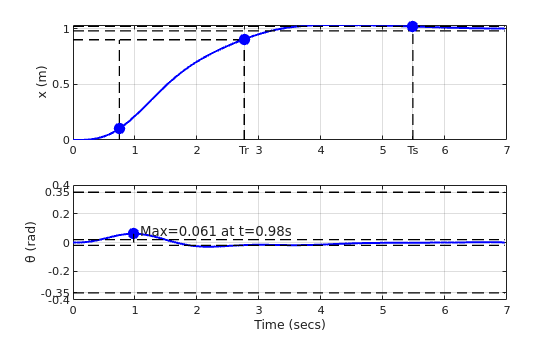

p = [p_ conj(p_) real(p_) real(p_) real(p_) real(p_)];
[K, Ke, sysC, thong_tin] = bo_dieu_khien_con_lac_xe_day(sys, p, 7);

Chọn 2 cực khác xa trục ảo $$j\omega$$ 1 lần và 2 cực khác xa trục ảo $$j\omega$$  lần so với cặp cực thống trị.

Đáp ứng của vị trí xe đẩy x với đầu vào [xd θd] = [1 0]:
Thời gian tăng: 0.479530 giây.
Thời gian xác lập: 3.938183 giây.
Độ vọt lố : 17.331987%.
Giá trị đỉnh: 1.173320.
Thời gian đỉnh: 1.052443 giây.

Đáp ứng của góc lắc con lắc θ với đầu vào [xd θd] = [1 0]:
Giá trị đỉnh: 0.299378.
Thời gian đỉnh: 0.458564 giây.


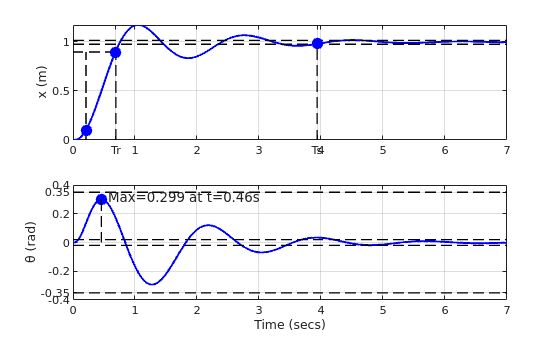

p = [p_ conj(p_) real(p_) real(p_) 15*real(p_) 15*real(p_)];
[K, Ke, sysC, thong_tin] = bo_dieu_khien_con_lac_xe_day(sys, p, 7);